# PW/TP 3-4: Ordinary Differential Equations - Applications (CH2)

## Solutions

**Exercise 1.** (2.74) An object moves along the $x$ axis, acted upon by a constant force. If its initial velocity in the positive direction is 40 meters/sec while 5 seconds later it is 20 meters/sec, find (a) the velocity at any time, (b) the position at any time assuming the object starts from the origin $x=0$.

Net force: $F=m\cdot a$


$$\frac{\mathrm d^2x}{\mathrm dt^2} = \frac{F}{m} = constant$$


syms v(t) t Fm
cond1 = v(0) == 40;
cond2 = v(5) == 20;
eq = diff(v,t) == Fm;
dsolve(eq,cond1)

$$ans = \mathrm{Fm}\,t+40$$

$v(t) = \frac{F}{m}\cdot t + 40$, using the second condition to find the value of the constant $\frac{\;F}{m}$.


$$v(t) = -4\cdot t + 40$$


syms x(t)
cond1 = x(0) == 0;
eq = diff(x,t) == -4*t+40;
dsolve(eq,cond1)

$$ans = -2\,t\,\left(t-20\right)$$

$x(t)=-2t^2+40$.

**Exercise 2.** (2.77) An electric circuit contains an 9 ohm resistor in series with an inductor of 0.5 henries and a battery of $E$ volts. At $t=0$ the current is zero. Find the current at any time $t>0$ and the maximum current if (a) $E=64$, (c) $E=32e^{-8t}$.

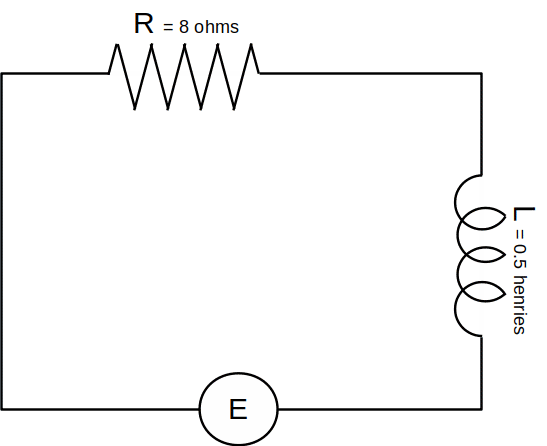

- Potential drop across $R$ = $8I$

- Potential drop across $L$ = $0.5\frac{\mathrm dI}{\mathrm dt}$

- Potential drop across $E$ = $-E$

Then by Kirchhoff's law,


$$8I+0.5 \frac{\mathrm dI}{\mathrm dt} -E = 0$$


(a) $E=64$

syms I(t) E
cond = I(0) == 0;
eq = 8*I+0.5*diff(I,t)-E == 0;
EN = 64;
dsolve(subs(eq,E,EN), cond)

$$ans = 8-8\,{\mathrm{e}}^{-16\,t}$$

(b) $E=8{\textrm{te}}^{-16t} \;$

EN = 8*t*exp(-16*t);
dsolve(subs(eq,E,EN),cond)

$$ans = 8\,t^{2}\,{\mathrm{e}}^{-16\,t}$$

OR  $\frac{\mathrm dI}{\mathrm dt} + 16I = 16te^{-16t}$ is a linear equation, thus can be solved as follows:

mu = exp(int(16,t));
syms c
eq = mu*I == int(mu*16*t*exp(-16*t),t) + c

$$eq(t) = {\mathrm{e}}^{16\,t}\,\text{I}\left(t\right)=8\,t^{2}+c$$

cond = I(0) == 0;
subs(subs(eq,t,0),I,0)

$$ans(t) = 0=c$$

eq = subs(eq,c,0);
eq = lhs(eq)*exp(-16*t) == rhs(eq)*exp(-16*t)

$$eq(t) = \text{I}\left(t\right)=8\,t^{2}\,{\mathrm{e}}^{-16\,t}$$

**Exercise 3.** (2.81 c) Find the orthogonal trajectories of the family of curves $y^2 = cx^2 - 2y$.

1) The differential equation of the family is: $2y\frac{\mathrm dy}{\mathrm dx} = 2cx-2\frac{\mathrm dy}{\mathrm dx}$, substituting in this $c=\frac{y^2+2y}{x^2}$

syms y(x) x c
eq = y(x)^2 == c*x^2-2*y(x);
eq_diff = diff(eq,x);
eq = simplify(subs(eq_diff,c,solve(eq,c)));
syms df
S = solve(subs(eq,diff(y,x),df),df)

$$S = \frac{y\left(x\right)\,\left(y\left(x\right)+2\right)}{x\,\left(y\left(x\right)+1\right)}$$

2) Since the slope of each member of the orthogonal family must be the negative reciprocal of this slope, we see that the slope of the orthogonal family is:

OF = -S^(-1)

$$OF = -\frac{x\,\left(y\left(x\right)+1\right)}{y\left(x\right)\,\left(y\left(x\right)+2\right)}$$

Solving this gives us the equation of the orthogonal trajectories:

syms y x c
eq = int(y*(y+2)/(y+1),y) == int(-x,x) + c;
eq = log(y+1) == c+x^2/2 + y^2/2 + y;
eq = exp(lhs(eq)) == exp(simplify(rhs(eq)))

$$eq = y+1={\mathrm{e}}^{\frac{x^{2}}{2}+\frac{y^{2}}{2}+y+c}$$

**Exercise 4.** (2.82) Find the equation of that curve passing through $\left(0,1\right)$ which is orthogonal to each member of the family $x^2+y^2=ce^x$.

1) The differential equation of the family $x^2+y^2=ce^x$

syms x y(x) c
eq = x^2+y^2 == c*exp(x);
eq = subs(diff(eq,x),c,solve(eq,c));
syms df;
S = solve(subs(eq,diff(y,x),df),df)

$$S = \frac{x^{2}-2\,x+{y\left(x\right)}^{2}}{2\,y\left(x\right)}$$

2) Since the slope of each member of the orthogonal family must be the negative reciprocal of this slope, we see that the slope of the orthogonal family is:

OF = -S^(-1)

$$OF = -\frac{2\,y\left(x\right)}{x^{2}-2\,x+{y\left(x\right)}^{2}}$$

We find the differential equation: $(x^2-2x+y^2)\mathrm dy + 2y\mathrm dx = 0$. Dividing by $x^{2\;} +y^2$, gives us $\mathrm dy + 2 \frac{y\mathrm dx - x\mathrm dy}{x^2+y^2} = 0$. 

syms y(x) x 
eq = atan(x/y);
simplify(diff(eq,x))

$$ans(x) = \frac{y\left(x\right)-x\,\frac{\partial }{\partial x}y\left(x\right)}{x^{2}+{y\left(x\right)}^{2}}$$

We know that $\frac{y\mathrm dx - x\mathrm dy}{x^2+y^2} = \mathrm d(\tan^{-1} \frac{x}{y})$, giving us the differential equation $\mathrm dy + \mathrm d(2\tan^{-1} \frac{x}{y}) = 0$ which gives as solution: $y+2\tan^{-1}(\frac{x}{y}) = c$.

Using the extra constraint they need to pass through $\left(0,1\right)$, to eliminate $c$. 

syms y x c
eq = y+2*atan(x/y) == c;
subs(subs(eq,x,0),y,1)

$$ans = 1=c$$

eq = subs(eq,c,1)

$$eq = y+2\,\mathrm{atan}\left(\frac{x}{y}\right)=1$$

And so we find: $y+2\tan^{-1}(\frac{x}{y}) = 1$

The family $x^2+y^2=ce^x$ and the member of the orthogonal family $y+2\tan^{-1}(\frac{x}{y}) = 1$ going through $\left(0,1\right)$ are shown below:

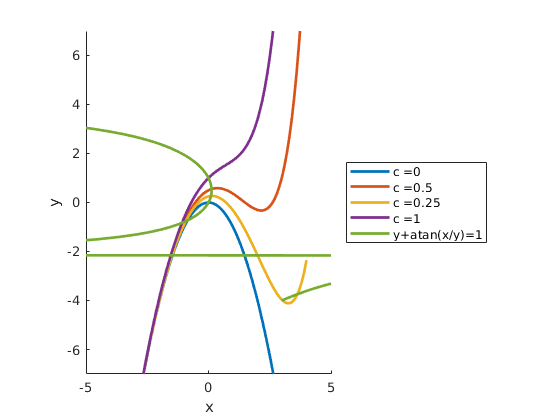

clear
figure
hold on
x = -4:0.1:4;
legends = {};
for c = [0, 1/2, 1/4, 1] 
    y = c*exp(x)-x.^2;
    plot(x, y, "LineWidth", 2)
    legends{end+1} = strcat('c = ', num2str(c));
end
y = -4:0.1:4;
x = y.*tan((1-y)./2);
plot(x,y, "LineWidth", 2)
legends{end+1} = 'y+atan(x/y)=1';

axis equal
axis([-5 5 -7 7])
legend(legends, 'Location', 'eastoutside')
xlabel('x'); ylabel('y')

**Exercise 5.** (2.85) A tank contains 100 gallons of water. A salt solution containing 2 lb of salt per gallon flows in at the rate of 3 gallons per minute and the well-stirred mixture flows out at the same rate. (a) How much salt is in the tank at any time? (b) When will the tank have 100 lb of salt?

Let $A$= lb salt in the tank at time $t$ minutes.

Rate of change of amount of salt = Rate of entrance - Rate of exit


$$\frac{\mathrm dA}{\mathrm dt} \frac{\text{lb}}{\text{min}} = 2 \frac{\text{lb}}{\text{gal}} \cdot 3 \frac{\text{gal}}{\text{min}} - \frac{A}{100} \frac{\text{lb}}{\text{gal}} \cdot 3 \frac{\text{gal}}{\text{min}}$$



$$\frac{\mathrm dA}{\mathrm dt} = 6 - \frac{3A}{100}$$


syms A(t) t
eq = diff(A,t) == 6 - (3*A)/100;
cond = A(0) == 0;
S = dsolve(eq,cond)

$$S = 200-200\,{\mathrm{e}}^{-\frac{3\,t}{100}}$$


$$A(t) = 200(1-e^{-0.03t})$$


When will $A=100$?

double(solve(S==100,t))

ans = 23.1049

$t=23,1$minutes.

**Exercise 6. **(2.89) The rate at which bacteria multiply is proportional to the instantaneous number present. If the original number doubles in 2 hours, in how many hours will it triple?

$B$ = the number of bacteria present after $t$ hours.

Time rate of change of $B$ is proportional to $B$: $\frac{\mathrm dB}{\mathrm dt} \sim B \Rightarrow \frac{\mathrm dB}{\mathrm dt} = k\cdot B$ with $B=B_0$ at $t=0$.

syms B(t) t B0 k
eq = diff(B,t) == k*B;
cond = B(0) == B0;
S = dsolve(eq,cond)

$$S = B_{0}\,{\mathrm{e}}^{k\,t}$$

Sk = solve(subs(S,t,2)==2*B0,k)

$$Sk = \frac{\log\left(2\right)}{2}$$

double(solve(subs(S,k,Sk)==3*B0,t))

ans = 3.1699

ans = 3.1699

**Exercise 7. **(2.93) It takes 15 minutes for an object to warm up from $10\;\textrm{°C}$ to $20\;\textrm{°C}$ in a room whose temperature is $30\;\textrm{°C}$. Assuming Newton's law of cooling, how long would it take to warm up from $20\;\textrm{°C}$ to $25\;\textrm{°C}$? 

$U$=temperature of object after $t$ minutes.

time rate of chage in temperature of an object $\;\sim \;$difference in temperature between object and surroundings.


$$\frac{\mathrm dU}{\mathrm dt} = k\cdot (U-30)$$


syms U(t) k 
eq = diff(U,t) == k*(U-30);
cond1 = U(0) == 10;
cond2 = U(15) == 20;
S = dsolve(eq,cond1)

$$S = 30-20\,{\mathrm{e}}^{k\,t}$$

Sk = solve(subs(S,t,15)==20,k)

$$Sk = -\frac{\log\left(2\right)}{15}$$

solve(subs(S,k,Sk)==25,t)

$$ans = 30$$

We reach the temperature of $25\;\textrm{°C}$ after 15 minutes.

**Exercise 8.** (2.75 a,b) A 64lb object falls from rest. The limiting velocity is 4 ft/sec. Find the velocity after $t$ seconds assuming a force of resistance proportional to (a) $v$ (b) $v^2$.

**Exercise 9.** (2.94) At $1:00$ P.M. the temperature of a tank of water is $200\;\textrm{°F}$. At $1:30$ P.M. its temperature is $160\;\textrm{°F}$. Assuming the surrounding temperature is maintained at $80\;\textrm{°F}$, (a) what is the temperature at $2:00$ P.M. and (b) at what time will the temperature be $100\;\textrm{°F}$? Assume Newton's law of cooling.

**Exercise 10.** (2.90) After 2 days, 10 grams of a radioactive chemical is preent. Three days later 5 grams is present. How much of the chemical was present initially assuming the rate of disintegration is proportional to the instantaneous amount which is present?

**Exercise 11.** (2.78) An electric circuit contains an 9 ohm resistor in series with an inductor of 0.5 henries and a battery of $E$ volts. At $t=0$ the current is zero. Find the current at any time $t>0$ if $E=64 \sin 8t$. What is the transient current and steady-stade current?

**Exercise 12.** (2.81 b) Find the orthogonal trajectories of the family of curves $x^2+y^2=cx$.

**Exercise 13.** (2.79 b) An electric circuit contains a 20 ohm resistor in series with a capacitor of 0.05 farads and a battery of $E$ volts. At $t=0$ there is no charge on the capacitor. Find the charge and current at any time $t>0$ if $E=100{\textrm{te}}^{-2t}$.

**Exercise 14.** (2.86) A tank contains 100 gallons of water. A salt solution containing 2 lb of salt per gallon flows in at the rate of 3 gallons per minute. How much salt is in the tank at any time if the well-stirred mixture flows out at the rate of (a) 2 gal/min (b) 4 gal/min? 